env = rlPredefinedEnv('BasicGridWorld')

env =   rlMDPEnv - 속성 있음:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: []


env.ResetFcn = @() 2

env =   rlMDPEnv - 속성 있음:

       Model: [1×1 rl.env.GridWorld]
    ResetFcn: @()2


rng(0)

qTable = rlTable(getObservationInfo(env),getActionInfo(env))

qTable =   rlTable - 속성 있음:

    Table: [25×4 double]


qRepresentation = rlQValueRepresentation(...
    qTable, getObservationInfo(env),getActionInfo(env))

qRepresentation =   rlQValueRepresentation - 속성 있음:

         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


qRepresentation.Options.LearnRate = 1

qRepresentation =   rlQValueRepresentation - 속성 있음:

         ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
    ObservationInfo: [1×1 rl.util.rlFiniteSetSpec]
            Options: [1×1 rl.option.rlRepresentationOptions]


agentOpts = rlQAgentOptions

agentOpts =   rlQAgentOptions - 속성 있음:

    EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                  SampleTime: 1
              DiscountFactor: 0.9900


agentOpts.EpsilonGreedyExploration.Epsilon = .04

agentOpts =   rlQAgentOptions - 속성 있음:

    EpsilonGreedyExploration: [1×1 rl.option.EpsilonGreedyExploration]
                  SampleTime: 1
              DiscountFactor: 0.9900


qAgent = rlQAgent(qRepresentation, agentOpts)

qAgent =   rlQAgent - 속성 있음:

    AgentOptions: [1×1 rl.option.rlQAgentOptions]


trainOpts = rlTrainingOptions

trainOpts =   rlTrainingOptions - 속성 있음:

                   MaxEpisodes: 500
            MaxStepsPerEpisode: 500
    ScoreAveragingWindowLength: 5
          StopTrainingCriteria: "AverageSteps"
             StopTrainingValue: 500
             SaveAgentCriteria: "none"
                SaveAgentValue: "none"
            SaveAgentDirectory: "savedAgents"
                       Verbose: 0
                         Plots: "training-progress"
                   StopOnError: "on"
                   UseParallel: 0
        ParallelizationOptions: [1×1 rl.option.ParallelTraining]


trainOpts.MaxEpisodes = 50;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.ScoreAveragingWindowLength = 30;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 11;

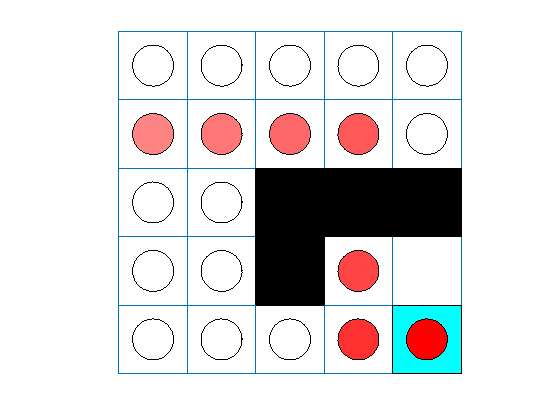

trainingStats = 다음 필드를 포함한 struct :
       EpisodeIndex: 1
      EpisodeReward: 11
       EpisodeSteps: 6
      AverageReward: 11
       AverageSteps: 6
    TotalAgentSteps: 6
        Information: [1×1 struct]
          EpisodeQ0: 10.4125
     SimulationInfo: [1×1 struct]


doTraining = true;

if doTraining
    trainingStats = train(qAgent, env, trainOpts)
else
    load('basicGWQAgent.mat', 'qAgent')
end

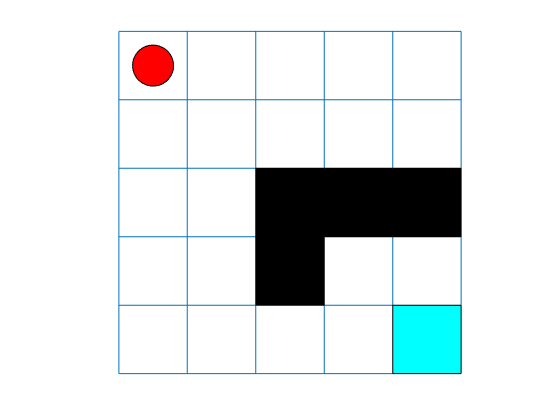

plot(env)

env.Model.Viewer.ShowTrace = true;
env.Model.Viewer.clearTrace;

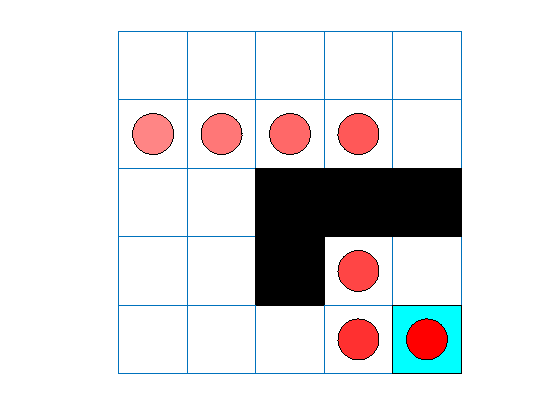

sim(qAgent,env)